# Problem 1, a

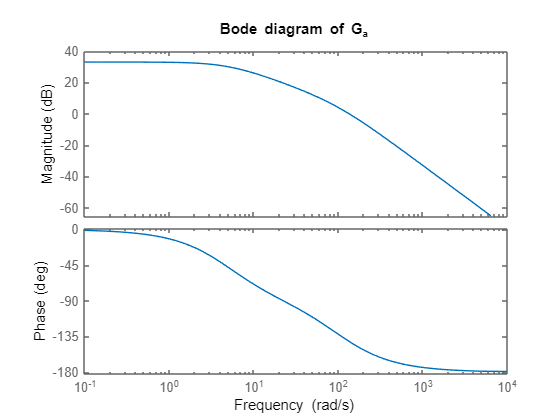


s = tf('s');
G_a= 45*(s/5 + 1)/((s/5 + 1)^2 * (s/100 + 1));
bode(G_a);
title("Bode diagram of G_a")

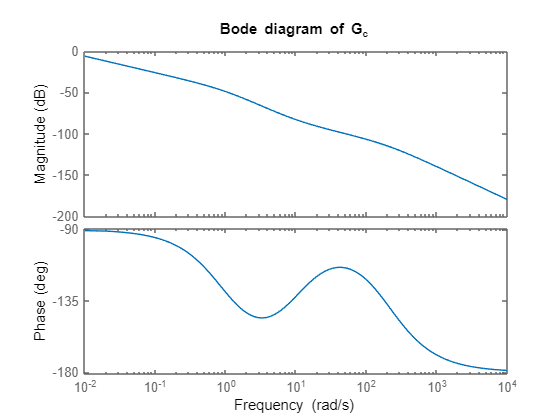


G_c = (s+10)/(10*s*(s+1)*(s+200));
bode(G_c)
title("Bode diagram of G_c")

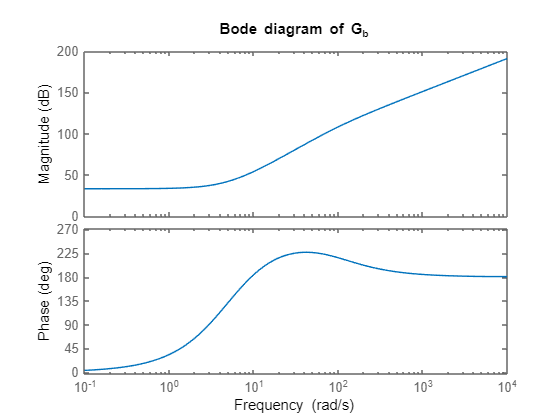


G_b = 45*(s/5 + 1)/(s/100 + 1) *( (s/5 + 1)^2);
bode(G_b)
title("Bode diagram of G_b")

## Problem 1, b

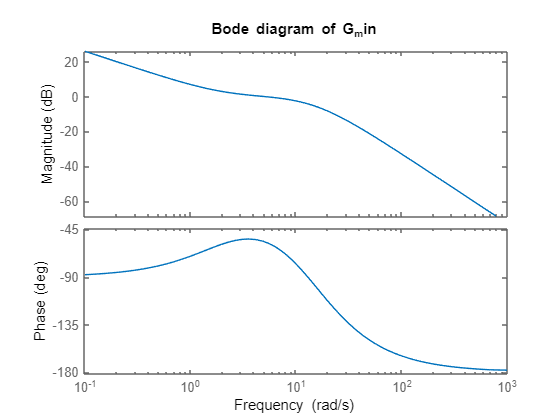

G_min = 1.99 *(s/2 + 1) * (s/8 + 1) /(s*(s/11 + 1) *(s/12 + 1) * (s/14 + 1));
bode(G_min)
title("Bode diagram of G_min")

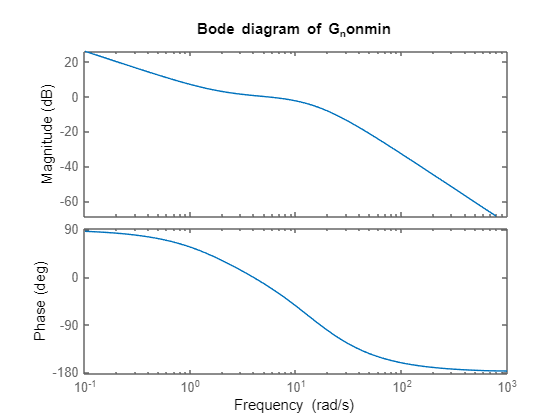

G_nonmin = 1.99*(s/2 - 1) * (s/8 + 1) /(s*(s/11 + 1) *(s/12 + 1) * (s/14 + 1));
bode(G_nonmin)
title("Bode diagram of G_nonmin")

## Problem 2

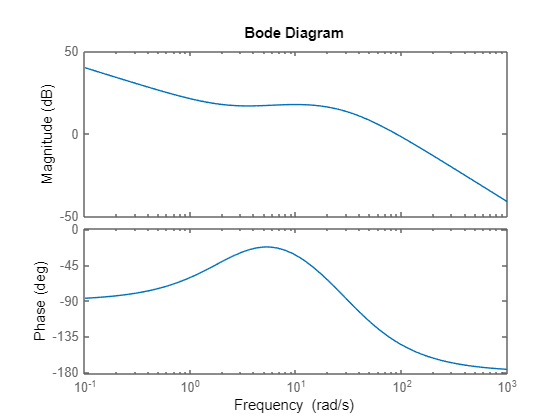


G = 10 * (s/2 + 1) * (s/4 + 1) /(s*(s/8 + 1) *(s/24 + 1) * (s/36 + 1));
bode(G)

## Problem 3

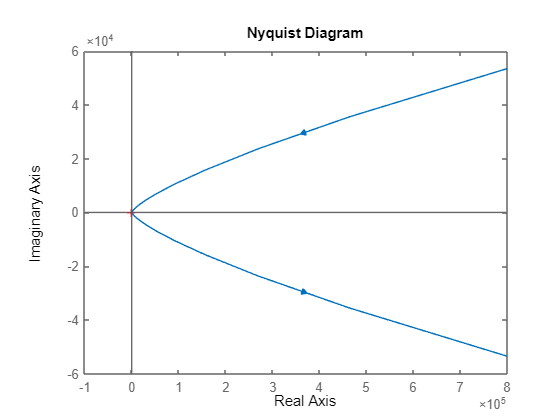

k=1;
GH = s^4 + 2*s^3 + (k+1)*s^2 + (k+1)*s + k - 1;
nyquistplot(GH)

## Problem 4

time = linspace(0, 2000, 2500000);
amp = 1;
phase_diffs = zeros(1, 50);
amps = zeros(1, 50);

freq = logspace(-3, 1, 50);

for i = 1:numel(freq)
    input_signal = amp * sin(freq(i) * time);
    output_signal = sys(input_signal, time);

    [Upeaks, Upeak_indices] = findpeaks(input_signal);
    time_first_peak_input = time(Upeak_indices(1));

    [Ypeaks, Ypeak_indices] = findpeaks(output_signal);
    time_first_peak_output = time(Ypeak_indices(1));

    temp_diff = time_first_peak_output - time_first_peak_input;
    phase_diffs(i) = temp_diff * freq(i) * 180 / pi;

    max_output = max(output_signal);
    amps(i) = 20 * log10(max_output);
end

subplot(2,1,1);
semilogx(freq, amps, 'LineWidth', 1);
grid on;
title('Bode Diagram');
xlabel('Frequency');
ylabel('Amplitude (dB)');

subplot(2,1,2);
semilogx(freq, phase_diffs, 'LineWidth', 1);
grid on;
xlabel('Frequency');
hold off

## Problem 5, a&b

% Gs = (1-s)*exp(-s)/((12*s+1)*(3*s+1)*(0.2*s+1)*(0.05*s+1));
% step(Gs)
% hold on
% G1 = exp(-4*s)/(19*s+1);
% %step(G1)
% %yline(0.63)
% G2 = exp(-4*s)/(13.4*s+1);
% % step(G2)
% %yline(0.28)
% G3 = exp(-4*s)/(12.42*s+1);
% % step(G3)
% G4 = exp(-4*s)/(13.25*s+1);
% step(G4)
% grid on

## Problem 5, c

G5 = exp(-3.17*s)/((2.99*s+1)*(11.09*s+1));
step(G5)
figure(2)
G6 = exp(-4*s)/((6.625*s+1)^2);
step(G6)

## Problem 5, d

[y, ~] = step(G, t);
[y1, ~] = step(G1, t);
mse1 = immse(y, y1);
[y2, ~] = step(G2, t);
mse2 = immse(y, y2);
[y3, ~] = step(G3, t);
mse3 = immse(y, y3);
[y4, ~] = step(Gb, t);
mse4 = immse(y, y4);
[y5, ~] = step(G5, t);
mse5 = immse(y, y5);
[y6, ~] = step(G6, t);
mse6 = immse(y, y6);
disp(['Mean Squared Error of G1: ', num2str(mse1)]);
disp(['Mean Squared Error of G2: ', num2str(mse2)]);
disp(['Mean Squared Error of G3: ', num2str(mse3)]);
disp(['Mean Squared Error of G4: ', num2str(mse4)]);
disp(['Mean Squared Error of G5: ', num2str(mse5)]);
disp(['Mean Squared Error of G6: ', num2str(mse6)]);

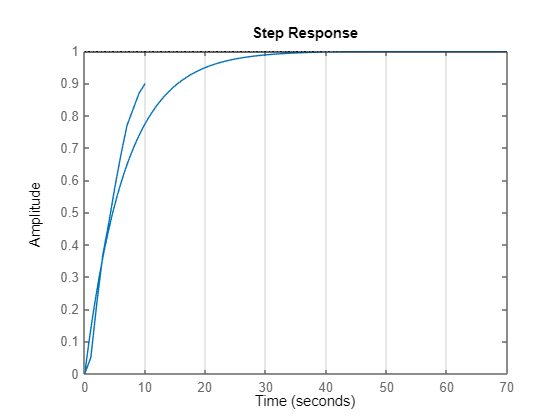

%% Problem 6
t = [0, 1, 2, 3, 4, 5, 6, 7, 8, 9, 10];
y = [0.0, 0.05, 0.22, 0.37, 0.47, 0.58, 0.68, 0.77, 0.82, 0.87, 0.90];
tq = [11, 12, 13, 14, 15];
yq = interp1(t, y, tq);
plot(t, y, '-', tq, yq, ':.')
hold on
yline(1)
hold on
step(1/(6.7*s + 1))
hold off
set(gca,'XGrid','on','YGrid','off')

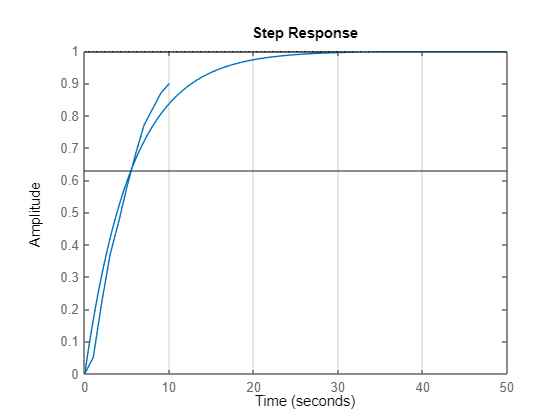

%annotation('line',[0.6571 0.1679],[0.9405 0.08571])
plot(t, y, '-', tq, yq, ':.')
hold on
yline(1)
hold on
yline(0.63)
hold on
step(1/(5.5*s + 1))
hold off
set(gca,'XGrid','on','YGrid','off')

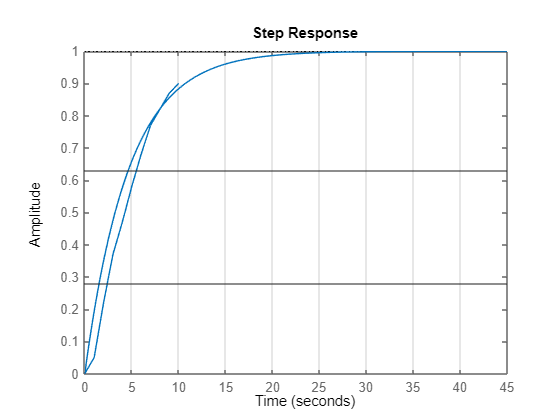

plot(t, y, '-', tq, yq, ':.')
hold on
yline(0.28)
hold on
yline(0.63)
hold on
step(1/(4.65*s + 1))
hold off
set(gca,'XGrid','on','YGrid','off')

N = 11;
n = 1;
t1 = linspace(0,10, N);
u = heaviside(t1)

u =     0.5000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


y(1) = 0;
phi = zeros(N, n+1);
Y = zeros(N,1);
phi(1, :) = [0 0];
for i = 2:N
    phi(i, :) = [-y(i-1) u(i-1)];
    Y(i) = y(i);
end

Teta = inv(phi'*phi)*phi'*Y

Teta =    -0.8560
    0.1698


tau = 1/(1+Teta(1))

tau = 6.9452

k = Teta(2)*tau

k = 1.1791

Gb = k/(tau * s + 1)

Gb =
 
     1.179
  -----------
  6.945 s + 1
 
Continuous-time transfer function.



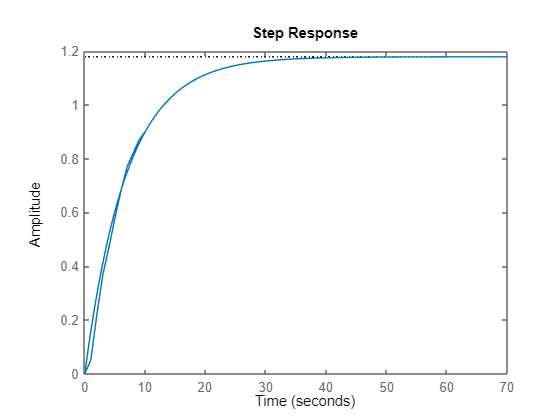

figure
plot(t, y)
hold on
grid on
step(Gb)
hold off


[yb, ~] = step(Gb, t);
[y1, ~] = step(1/(6.7*s + 1), t);
[y2, ~] = step(1/(5.5*s + 1), t);
[y3, ~] = step(1/(4.65*s + 1), t);
mse1 = immse(y', y1)

mse1 = 0.0076

mse2 = immse(y', y2)

mse2 = 0.0036

mse3 = immse(y', y3)

mse3 = 0.0062

mseb = immse(y', yb)

mseb = 0.0021